## **Question 1**

- Consider the the Lorenz-63 model with the setting used in Project 1. The data assimilation problem is posed over the interval [0, T], starting with initial background states from N (x b 0 , B0). Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from Project 1.

**The code below is taken directly from my Project 1 implementation (modified to the L63 system)**

**1.1)**

- Implement the Lorenz-63 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Setting seed for reproducibility
rng(38199650)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs_states = 2;

% Inital conditions
x0 = [-10.0375; -4.3845; 34.6514];
B0 = [12.4294, 12.4323, -0.2139; 12.4323, 16.0837, -0.0499; -0.2139, -0.0499, 14.7634];

% Time steps
dt = 0.1; % time step unit
h = dt/200;
T_max = 0.2;
T = 0:dt:T_max;

% Array initalization
X = zeros(3,round(T_max/dt) + 1);


% iterate through timesteps
x = x0;
X(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X(:, i+1) = x;
end

% Generating observations

n_obs = 1;
% Apply observation operator and add random noise to reference trajectory
% Generating observation operator (observing first two states)

% Not 100% on this size (0 x3)
H = [1, 0, 0;
    0, 1, 0;
    0, 0, 0];

% Applying observation vector to reference trajectory
% H * Reference -> Observations, Clone Observatations + noise -> ensemble 
X_obvs = H * X;
X_obvs_ens = repmat(X_obvs, 1,1, n_obs);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.25;
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
obvs_noise(3,:,:) = 0;
X_obvs_ens = X_obvs_ens + obvs_noise;


% Draw X0 from dist
x0_b = mvnrnd(x0,B0)';
% Run model with background
X_b = zeros(3,round(T_max/dt) + 1);
x = x0_b;
X_b(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X_b(:, i+1) = x;
end

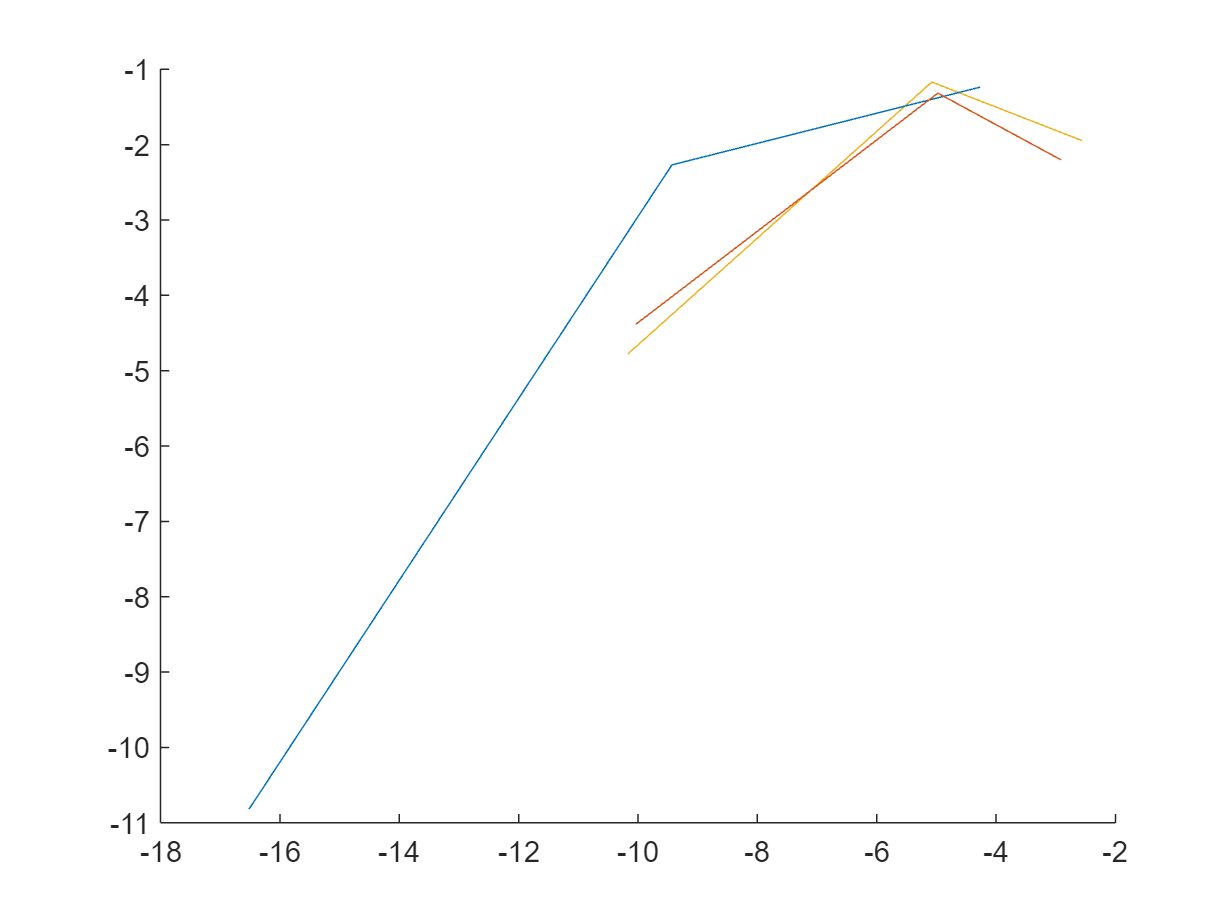

clf
hold on
plot3(X_b(1, :), X_b(2, :), X_b(3, :));
plot3(X(1, :), X(2, :), X(3, :));
plot3(X_obvs_ens(1, :), X_obvs_ens(2, :), X_obvs_ens(3, :));

% Setup minimizer

%a = x0_b; b = X_obvs_ens; % Assign parameter values
f = @(x)var4(x,x0_b,X_obvs_ens,T_max,dt);

options = optimoptions('fminunc','Display','iter','Algorithm','trust-region','SpecifyObjectiveGradient',true);

[a,b] = f(x0)

a = 4.9688

b =     0.9293
   -3.3160
   -4.6928


x = x0_b

x =   -16.5190
  -10.8205
   33.0062


for k = 1:20
    xb = x
    f = @(x)var4(x,xb,X_obvs_ens,T_max,dt);
    [x0_a,fval,exitflag,output] = fminunc(f,x,options)
    x = x0_a
end

xb =   -16.5190
  -10.8205
   33.0062



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0             802.92                           156                
     1            31.5894             10           53.2           1
     2            5.63567         1.1398           3.69           1
     3            3.13817       0.526754           3.52           1
     4            2.73977       0.220915           1.97           1
     5            2.44705       0.232183            1.8           1
     6            2.26266       0.123774          0.836           1
     7            2.24803      0.0332249          0.353           1
     8            2.23267      0.0491905          0.368           1
     9             2.2208      0.0244734          0.159           1
    10            2.22039     0.00561796         0.0581           1
    11            2.22026     0.00484235         0.0447           1
    12            2.21859     0.00493123        

x0_a =   -10.1958
   -4.7402
   35.2705


fval = 2.2180

exitflag = 3

output = struct with fields:
         iterations: 20
          funcCount: 21
           stepsize: 3.6777e-05
       cgiterations: 18
      firstorderopt: 0.0019
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the final change in function value relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative objective function value is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1958
   -4.7402
   35.2705


xb =   -10.1958
   -4.7402
   35.2705



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.408754                         0.587                
     1            0.39997      0.0413263           0.23           1
     2           0.394514      0.0280271          0.266           1
     3             0.3937     0.00593665        0.00953           1
     4             0.3937    0.000660573        0.00953           1
     5             0.3937    0.000165143        0.00953           0
     6             0.3937    4.12858e-05        0.00953           0
     7             0.3937    1.03215e-05        0.00953           0
     8             0.3937    2.58036e-06        0.00953           0
     9             0.3937    6.45091e-07        0.00953           0

Local minimum possible.

fminunc stopped because the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3937

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 10
           stepsize: 6.4509e-07
       cgiterations: 4
      firstorderopt: 0.0095
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 6.450911e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb =   -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =   -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.1663
   -4.7644
   35.3124


xb = 3×1
  -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
  -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
  -10.1663
   -4.7644
   35.3124


xb = 3×1
  -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
  -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
  -10.1663
   -4.7644
   35.3124


xb = 3×1
  -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
  -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
  -10.1663
   -4.7644
   35.3124


xb = 3×1
  -10.1663
   -4.7644
   35.3124



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.393201                        0.0268                
     1           0.393201     0.00166797         0.0268           1
     2           0.393201    0.000416993         0.0268           0
     3           0.393201    0.000104248         0.0268           0
     4           0.393201     2.6062e-05         0.0268           0
     5           0.393201    6.51551e-06         0.0268           0
     6           0.393201    1.62888e-06         0.0268           0
     7           0.393201    4.07219e-07         0.0268           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
  -10.1663
   -4.7644
   35.3124


fval = 0.3932

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.0722e-07
       cgiterations: 1
      firstorderopt: 0.0268
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.072195e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
  -10.1663
   -4.7644
   35.3124


x0, x0_b, x0_a

x0 = 3×1
  -10.0375
   -4.3845
   34.6514


x0_b = 3×1
  -16.5190
  -10.8205
   33.0062


x0_a = 3×1
  -10.1663
   -4.7644
   35.3124


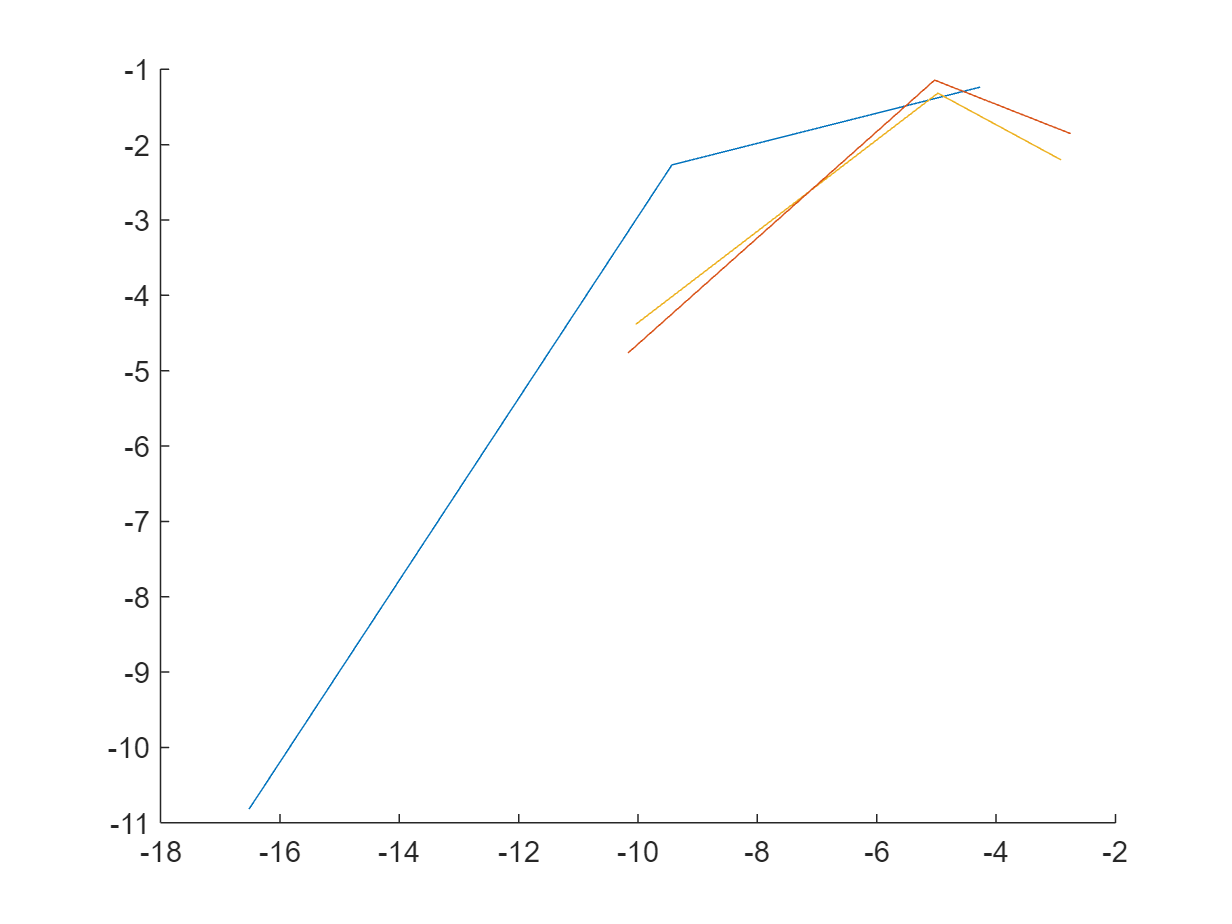

X_a = zeros(3,(round(T_max/dt)) + 1);
x = x0_a;
X_a(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X_a(:, i+1) = x;
end
clf
hold on
plot3(X_b(1, :), X_b(2, :), X_b(3, :));
plot3(X_a(1, :), X_a(2, :), X_a(3, :));
plot3(X(1, :), X(2, :), X(3, :));

Q2: